# Q4.

## (a)

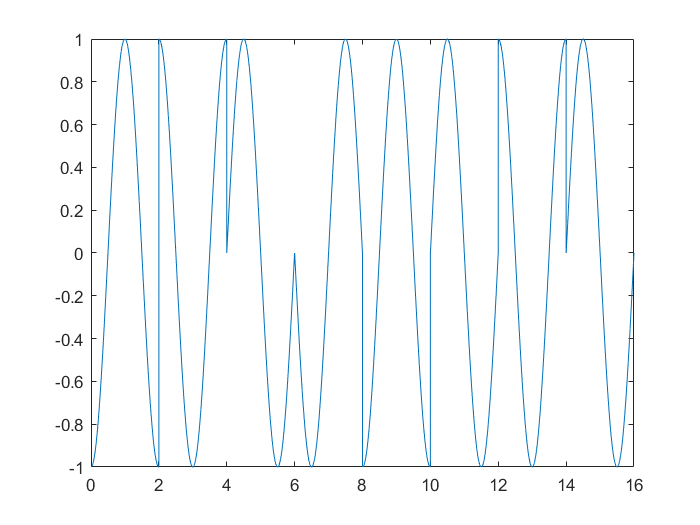

T_b = 1;            % bit interval
h = 2;              % number of bits per symbol
T = h*T_b;          % symbol interval
binary_seq = [1 1 0 0 1 0 0 1 1 1 1 0 0 0 1 0];
signals = length(binary_seq)/h;
resolution = 1000;  % number of data points for a smooth plot
t = linspace(0,T,resolution);

% generating symbols according to the mapping rule
s_0_t = sqrt(2/T)*cos(2*pi*t/T + pi*0/2); % i = 0
s_1_t = sqrt(2/T)*cos(2*pi*t/T + pi*1/2); % i = 1
s_2_t = sqrt(2/T)*cos(2*pi*t/T + pi*2/2); % i = 2
s_3_t = sqrt(2/T)*cos(2*pi*t/T + pi*3/2); % i = 3

% constructing the signal
tx_signal = zeros(signals, resolution);
signal = 1;
for index = 1:h:length(binary_seq) %initVal:step:endVal
    if binary_seq(index) == 0 && binary_seq(index +1) == 0
        tx_signal(signal,:) = s_0_t;
    elseif binary_seq(index) == 0 && binary_seq(index +1) == 1
        tx_signal(signal,:) = s_1_t;
    elseif binary_seq(index) == 1 && binary_seq(index +1) == 1
        tx_signal(signal,:) = s_2_t;
    elseif binary_seq(index) == 1 && binary_seq(index +1) == 0
        tx_signal(signal,:) = s_3_t;
    end
    signal = signal +1;
end

tx_signal = reshape(tx_signal',1,[]); % pre-processing for plotting
plot(linspace(0,signals*T, length(tx_signal)), tx_signal);

a = magic(4)

a =     16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1


b = reshape(a', 1, [])

b =     16     2     3    13     5    11    10     8     9     7     6    12     4    14    15     1
